# DCM perturbation example 1

This code uses two DCMs of one subject's different sessions of resting-state EEG.The sessions are 'baseline' and 'follow-up.'  

### Load DCMs and plot parameters

First we need run setup.

perturbation_setup;

Setup ran successfully.


Then we load DCMs in repsoitory path, plot bar graph of parameters.

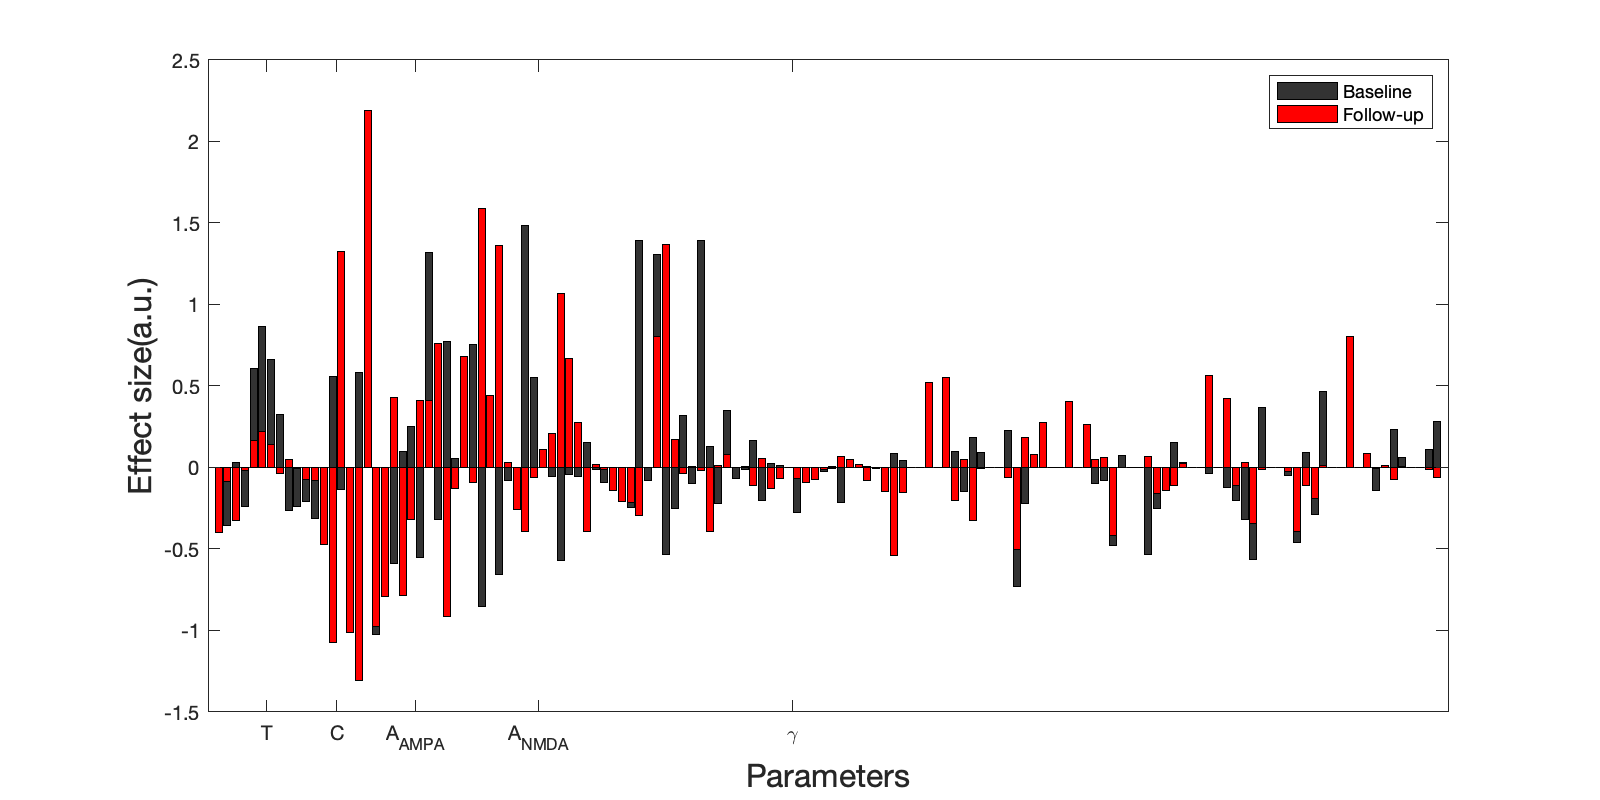

BDCM = load(fullfile(setupPath,"DCM_S2_baseline_DMN_140_e2.mat"));
PDCM = load(fullfile(setupPath,"DCM_S2_followup_DMN_140_e2.mat"));

% Convert posterior parameter structure to vector form
vBEp = spm_vec(BDCM.DCM.Ep);
vPEp = spm_vec(PDCM.DCM.Ep);

parameters ={'T','C','A','AN','H'};

% Get parameter index
pInd = spm_fieldindices(BDCM.DCM.Ep,parameters{:});


H1 = figure('Color','w','Position',[1 1 800 400]);
bb = bar(1:numel(pInd),vBEp(pInd),'FaceColor',[.2 .2 .2]);
hold on
pb = bar(1:numel(pInd),vPEp(pInd),'FaceColor','r');

xticks([6.5 14.5 23.5 37.5 66.5]);
xticklabels({'T','C','A_{AMPA}','A_{NMDA}','\gamma'});
xlabel('Parameters','FontSize',16);
ylabel('Effect size(a.u.)','FontSize',16);
legend([bb pb],{'Baseline','Follow-up'});

### Plot original CSDs of DCMs

We plot CSDs from two DCMS. CSDs were complex value, we evaulate absolute of CSDs and Ucledian normalization.


$$CSD(e,f) = \frac{CSD_{\text{raw}}(e,f)}{\sqrt {\sum_{e \in E} \sum_{f \in F} CSD_{\text{raw}}(e,f)^2}}$$


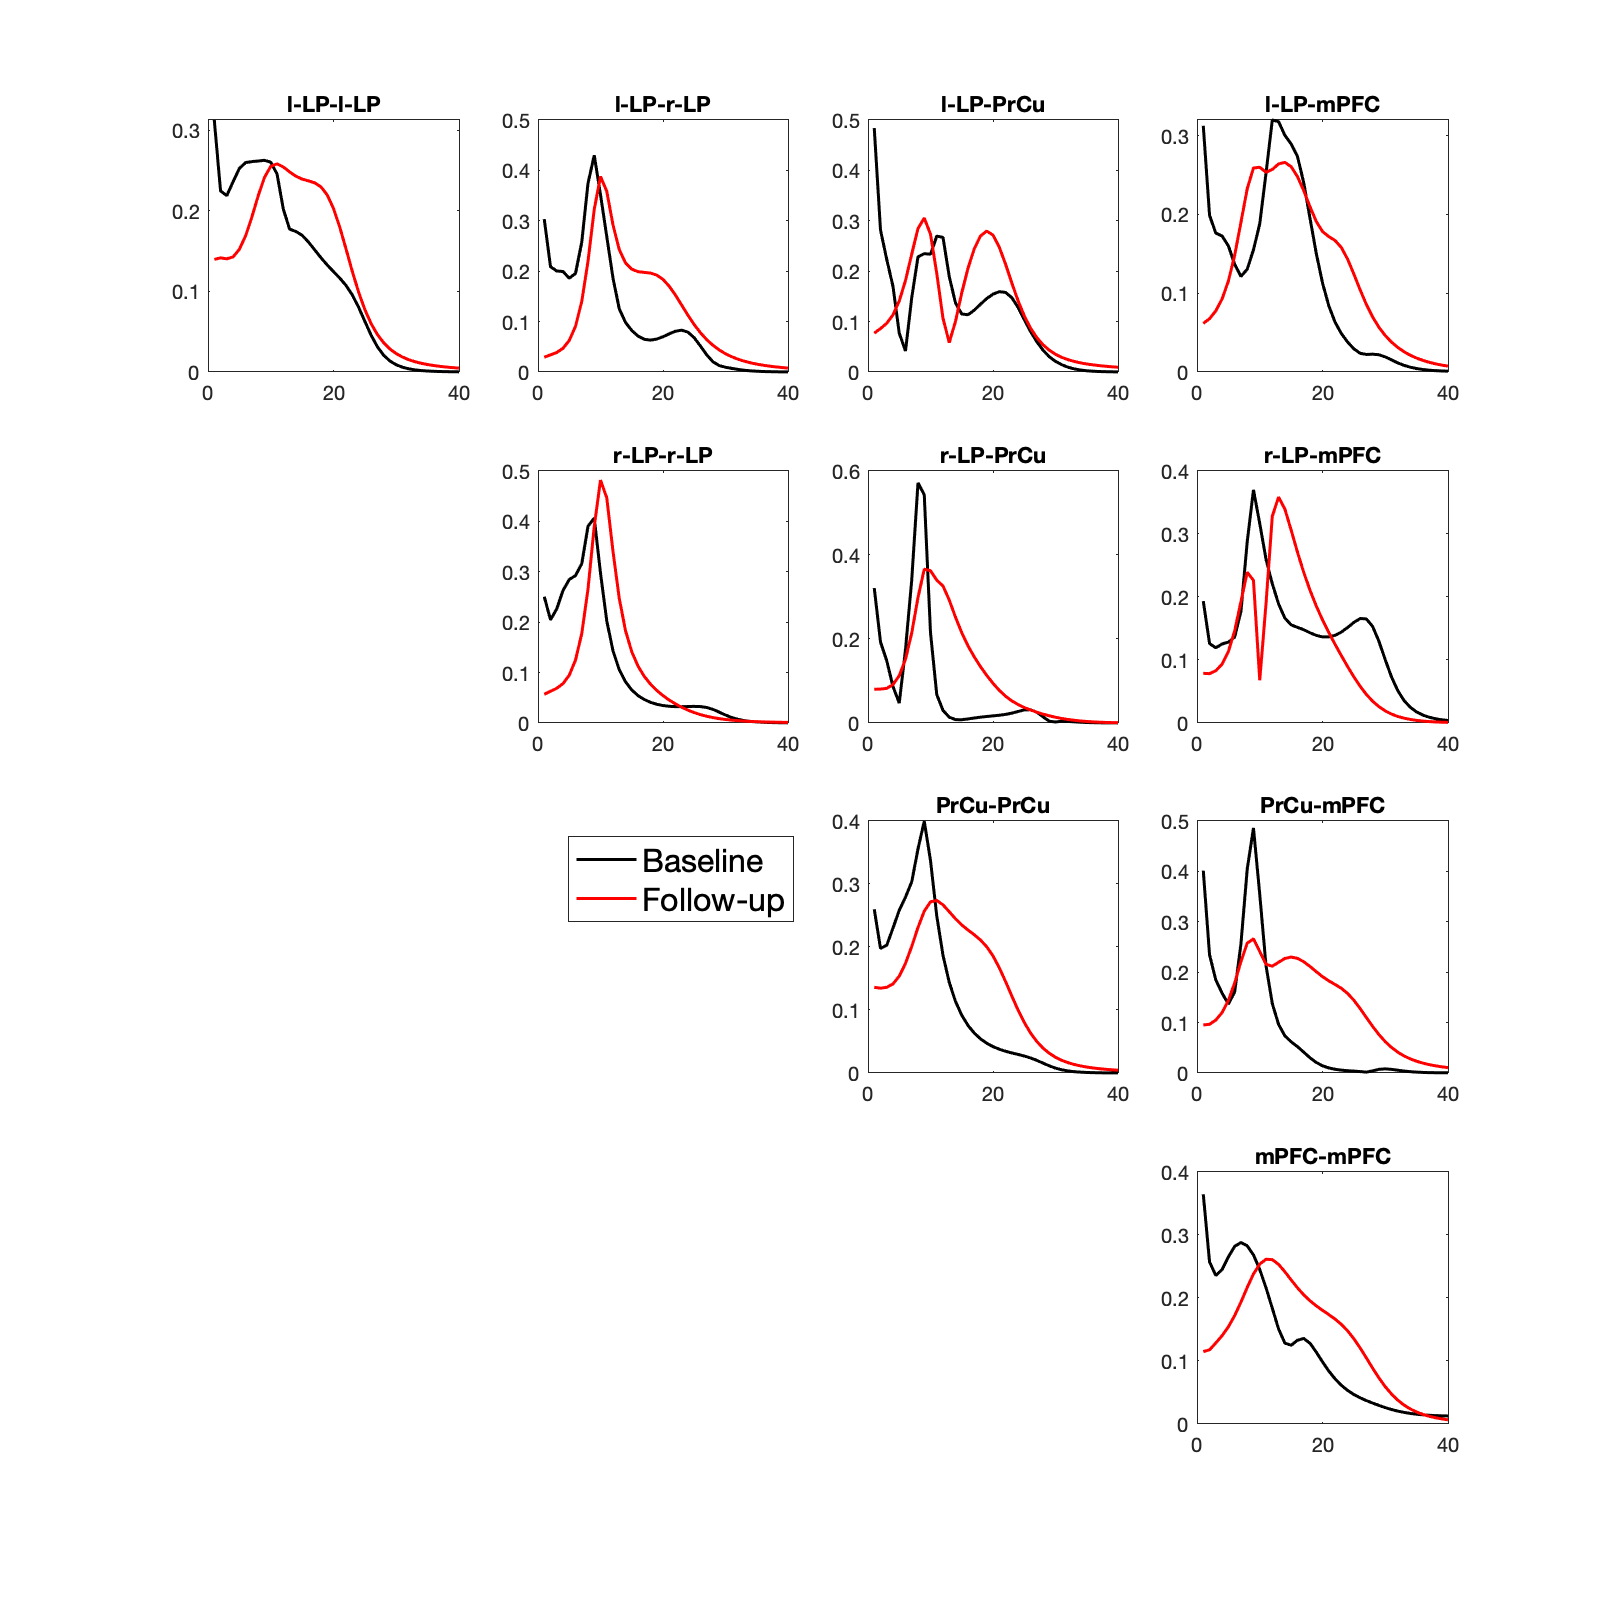

aBCSDs = abs(BDCM.DCM.Hs{1});
aPCSDs = abs(PDCM.DCM.Hs{1});

naBCSDs = aBCSDs./sqrt(sum(aBCSDs.*aBCSDs));
naPCSDs = aPCSDs./sqrt(sum(aPCSDs.*aPCSDs));

[nHz,nNode,~] = size(naBCSDs);
% Plot CSDs
H2 = figure('Color','w','Position',[1 1 800 800]);
for n1 = 1:nNode
    for n2 = 1:nNode
        if n1 > n2, continue, end
        subplot(nNode,nNode,(n1 -1)*nNode + n2);
        bcl = plot(1:nHz,naBCSDs(1:nHz,n1,n2),'LineWidth',1.5,'Color','k');
        hold on
        pcl = plot(1:nHz,naPCSDs(1:nHz,n1,n2),'LineWidth',1.5,'Color','r');
        title([BDCM.DCM.Sname{n1} '-' BDCM.DCM.Sname{n2}]);
    end
end
H2lgd = legend([bcl,pcl],{'Baseline','Follow-up'},'FontSize',16,'Position',[0.375 0.425 0.1 0.05]);

### Whole parameter perturbation

In this section we replace all parameter values from baseline to follow-up session and display perturbed CSD.

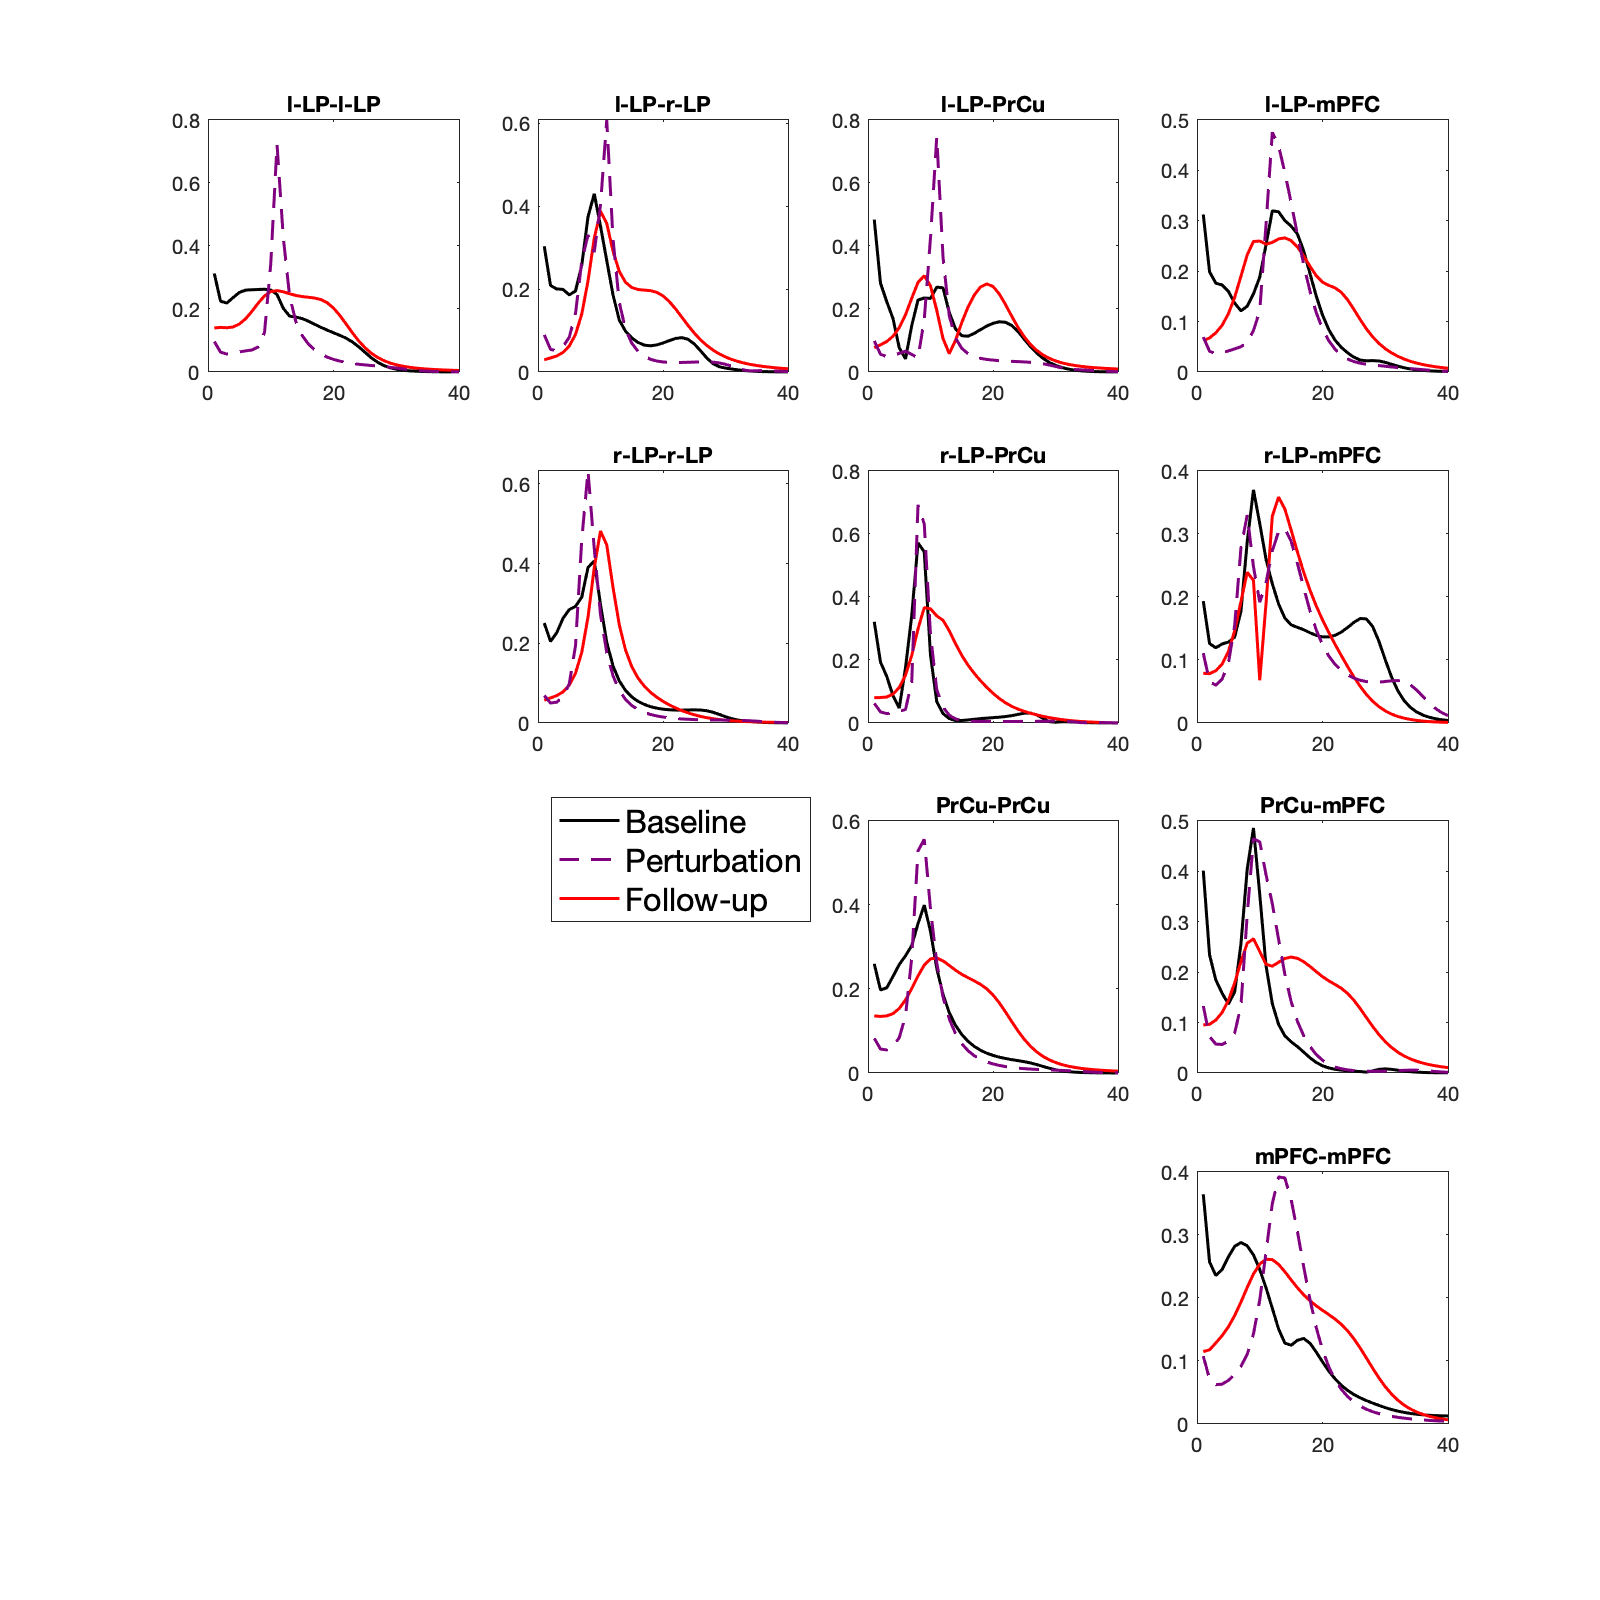

percentile = 20;

vNEp = vBEp + (percentile/100) .* (vPEp - vBEp);
NEp = spm_unvec(vNEp,BDCM.DCM.Ep);
% Get model structure and external input
M = BDCM.DCM.M;
U = BDCM.DCM.xU;
% Modify observation parameter and denoise 
M = rmfield(M,'U');
M.dipfit.type = 'LFP';
M.U = 1;
M.l = nNode;

NEp.L = ones(1,nNode);
NEp.b = NEp.b - 32;
NEp.c = NEp.c - 32;

% Generate CSD
NCSDs  = spm_csd_mtf(NEp,M,U);

% Prepare plot
aNCSDs  = abs(NCSDs{1});
naNCSDs = aNCSDs./sqrt(sum(aNCSDs.*aNCSDs));

H3 = figure('Color','w','Position',[1 1 800 800]);
for n1 = 1:nNode
    for n2 = 1:nNode
        if n1 > n2, continue, end
        subplot(nNode,nNode,(n1 -1)*nNode + n2);
        bcl = plot(1:nHz,naBCSDs(1:nHz,n1,n2),'LineWidth',1.5,'Color','k');
        hold on
        pcl = plot(1:nHz,naPCSDs(1:nHz,n1,n2),'LineWidth',1.5,'Color','r');
        ncl = plot(1:nHz,naNCSDs(1:nHz,n1,n2),'--','LineWidth',1.5,'Color',[.5 0 .5]);
        title([BDCM.DCM.Sname{n1} '-' BDCM.DCM.Sname{n2}]);
    end
end
H2lgd = legend([bcl,ncl,pcl],{'Baseline','Perturbation','Follow-up'},...
               'FontSize',16,'Position',[0.375 0.425 0.1 0.075]);